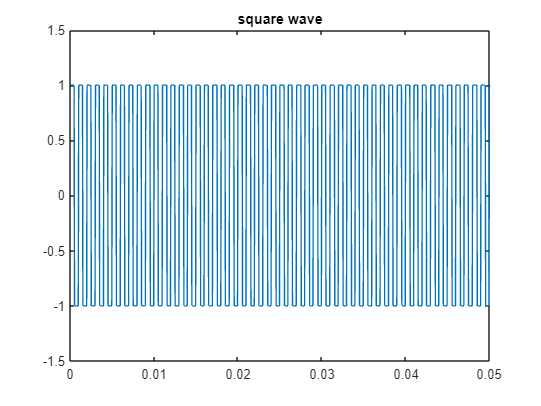

T=0.02;
N=256;
F = 1000;
Fs = 20000; %sampling frequency
t = 0:1/Fs:T;
x = square(2*pi*F*t); %Square wave
figure(1);
plot(t,x)
title('square wave')
ylim([-1.5, 1.5])

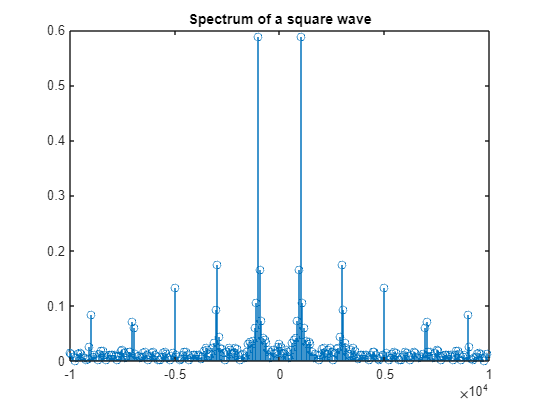

Y = fft(x,N); %Fast fourier transform
Y = fftshift(Y); %Shifting FFT to center
Y = abs(Y);
Y = Y/N;
f = -1*(Fs/2):Fs/N:(Fs/2)-1;
figure(2);
stem(f,Y) %Plotting spectrum of the given square wave @discrete
title('Spectrum of a square wave')